# First Problem

***1.Newton Method***

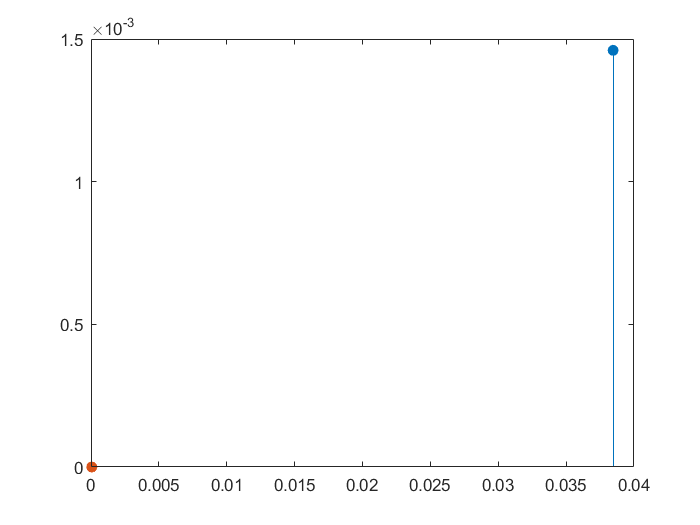

Trail_Members = 'x(1): -0.0384615385 we Have x(1)-x(0) that is:-0.0384615385 && f(x(1)) is 0.0014603275: '

Trail_Members = 'x(2): -0.0385178684 we Have x(2)-x(1) that is:-0.0000563299 && f(x(2)) is 0.0000000031: '

root =     'root finded:-0.0385178684 
     Number of goneStages: 2'


x0 = 0; %input('enter the approximate root: ');
syms f(x)
figure();
xlabel("|x(N)-x(N-1)|");
ylabel("f(x(N))");
f(x) = sin(x)*exp(x)+25*x+1;
df = diff(f,x);
index_N = 1;
while(true)
    x1 = vpa(x0 - (f(x0)/vpa(df(x0))));
    stem(abs(x1-x0),f(x1),'filled')
    hold on
    Trail_Members = sprintf('x(%d): %.10f we Have x(%d)-x(%d) that is:%.10f && f(x(%d)) is %.10f: ',index_N,x1,index_N,index_N-1,x1-x0,index_N,f(x1))
    if(f(x1) == 0 ||  abs(x1-x0)< 10^(-4)) % we use 10^(-4) as the HW says
        root = sprintf('root finded:%.10f \nNumber of goneStages: %d',x1,index_N)
        break;
    end
 index_N = index_N + 1; 
    x0 = x1;
end

***2.Fixed point Method***

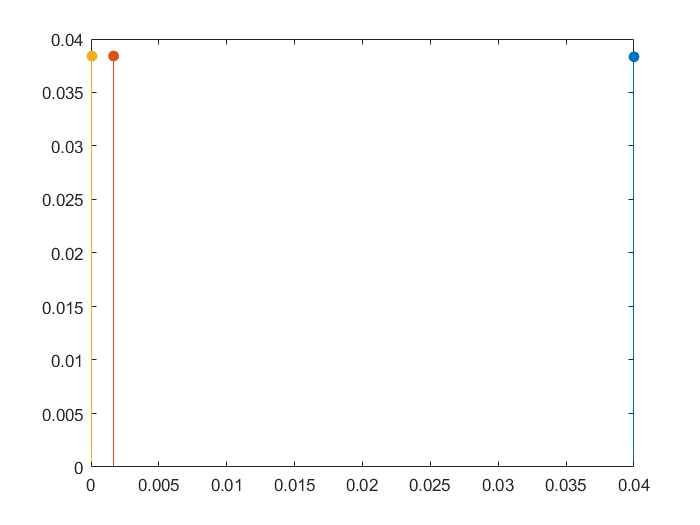

Trail_Members = 'x(1): 0.0400000000 we have x(1)-x(0) that is: 0.0400000000 && f(x(1)) is 0.0383351468'

Trail_Members = 'x(2): 0.0383351468 we have x(2)-x(1) that is: -0.0016648532 && f(x(2)) is 0.0384070597'

Trail_Members = 'x(3): 0.0384070597 we have x(3)-x(2) that is: 0.0000719129 && f(x(3)) is 0.0384039582'

root =     'root finded: 0.0384070597 
     Number of goneStages: 3'


x0 = 0; %input('enter the approximate root: ');
syms f(x)
figure();
xlabel("x(N)-x(N-1)");
ylabel("f(x(N))");
f(x) = (1-sin(x)*exp(x))/25;
index_N = 1;
while(true)
    x1 = vpa(f(x0));
    stem(abs(x1-x0),f(x1),'filled')
    hold on
    Trail_Members = sprintf('x(%d): %.10f we have x(%d)-x(%d) that is: %.10f && f(x(%d)) is %.10f',index_N,x1,index_N,index_N-1,x1-x0,index_N,f(x1))
    if(f(x1) == 0 || abs(x1-x0) < 10^(-4))  % we use 10^(-4) as the HW says
       root = sprintf('root finded: %.10f \nNumber of goneStages: %d',x1,index_N)
       break;
    end
index_N = index_N + 1;
x0 = x1;
end

***3.secant Method***

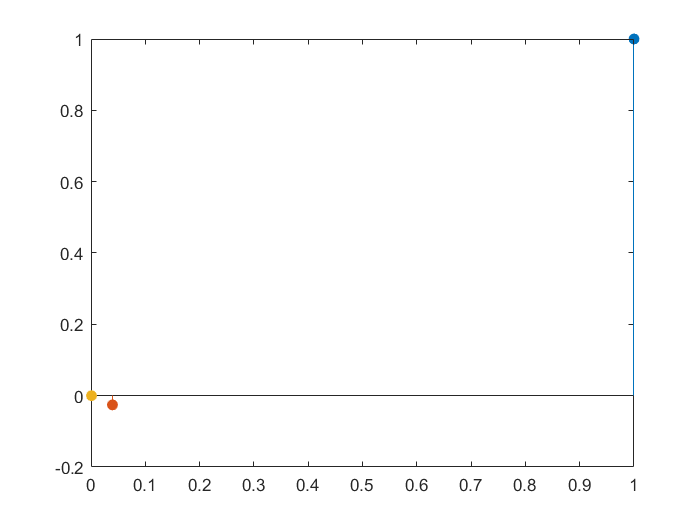

Trail_Members = 'x(1): 0.0000000000 we have x(1)-x(0) that is: 1.0000000000 && f(x(1)) is 1.0000000000'

Trail_Members = 'x(2): -0.0395107621 we have x(2)-x(1) that is: -0.0395107621 && f(x(2)) is -0.0257392721'

Trail_Members = 'x(3): -0.0385193033 we have x(3)-x(2) that is: 0.0009914588 && f(x(3)) is -0.0000371973'

Trail_Members = 'x(4): -0.0385178684 we have x(4)-x(3) that is: 0.0000014349 && f(x(4)) is 0.0000000014'

root =     'root finded: -0.0385178684 
     Number of goneStages: 4'


x0 = -1; %input('enter first guess of root');
x1 =  0; %input('enter second guess of root');
syms f(x)
figure();
xlabel("x(N)-x(N-1)");
ylabel("f(x(N))");
f(x) = sin(x)*exp(x)+25*x+1;
index_N = 1;
while(true)
    stem(abs(x1-x0),f(x1),'filled');
    hold on
    Trail_Members = sprintf('x(%d): %.10f we have x(%d)-x(%d) that is: %.10f && f(x(%d)) is %.10f',index_N,x1,index_N,index_N-1,x1-x0,index_N,f(x1))
    rootFinder = x1 - (f(x1)*(x1-x0))/(f(x1)-f(x0));
    if(abs(rootFinder - x1) < 10^(-4))
        Trail_Members = sprintf('x(%d): %.10f we have x(%d)-x(%d) that is: %.10f && f(x(%d)) is %.10f',index_N+1,rootFinder,index_N+1,index_N,rootFinder-x1,index_N+1,f(rootFinder))
        root = sprintf('root finded: %.10f \nNumber of goneStages: %d',rootFinder,index_N + 1)
        break
    else
        x0 = x1;
        x1 = rootFinder;
        index_N = index_N + 1;
    end
end

***4.Bisection***

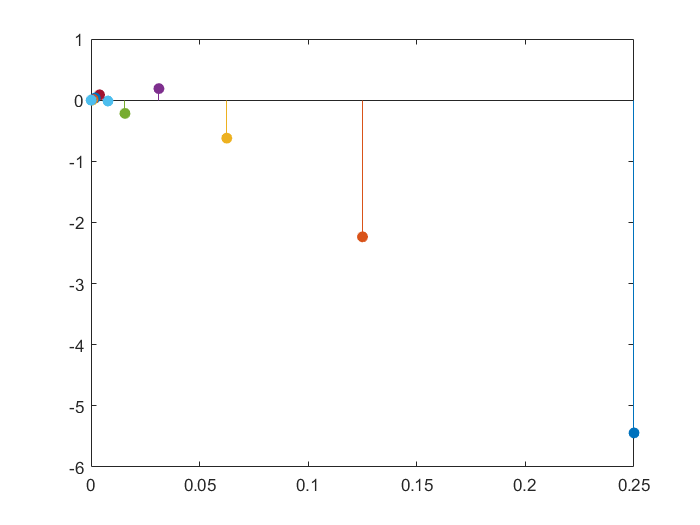

wholeData = 'a = -1.0000000000 && b = 0.0000000000 && c = -0.5000000000'

wholeData = 'a = -0.5000000000 && b = 0.0000000000 && c = -0.2500000000'

Trail_Members = 'x(2): -0.2500000000 we have x(2)-x(1) that is: 0.2500000000 && f(x(2)) is -5.4426783972'

wholeData = 'a = -0.2500000000 && b = 0.0000000000 && c = -0.1250000000'

Trail_Members = 'x(3): -0.1250000000 we have x(3)-x(2) that is: 0.1250000000 && f(x(3)) is -2.2350250660'

wholeData = 'a = -0.1250000000 && b = 0.0000000000 && c = -0.0625000000'

Trail_Members = 'x(4): -0.0625000000 we have x(4)-x(3) that is: 0.0625000000 && f(x(4)) is -0.6211750991'

wholeData = 'a = -0.0625000000 && b = 0.0000000000 && c = -0.0312500000'

Trail_Members = 'x(5): -0.0312500000 we have x(5)-x(4) that is: 0.0312500000 && f(x(5)) is 0.1884663910'

wholeData = 'a = -0.0625000000 && b = -0.0312500000 && c = -0.0468750000'

Trail_Members = 'x(6): -0.0468750000 we have x(6)-x(5) that is: -0.0156250000 && f(x(6)) is -0.2165870592'

wholeData = 'a = -0.0468750000 && b = -0.0312500000 && c = -0.0390625000'

Trail_Members = 'x(7): -0.0390625000 we have x(7)-x(6) that is: 0.0078125000 && f(x(7)) is -0.0141189863'

wholeData = 'a = -0.0390625000 && b = -0.0312500000 && c = -0.0351562500'

Trail_Members = 'x(8): -0.0351562500 we have x(8)-x(7) that is: 0.0039062500 && f(x(8)) is 0.0871589798'

wholeData = 'a = -0.0390625000 && b = -0.0351562500 && c = -0.0371093750'

Trail_Members = 'x(9): -0.0371093750 we have x(9)-x(8) that is: -0.0019531250 && f(x(9)) is 0.0365163235'

wholeData = 'a = -0.0390625000 && b = -0.0371093750 && c = -0.0380859375'

Trail_Members = 'x(10): -0.0380859375 we have x(10)-x(9) that is: -0.0009765625 && f(x(10)) is 0.0111977512'

wholeData = 'a = -0.0390625000 && b = -0.0380859375 && c = -0.0385742188'

Trail_Members = 'x(11): -0.0385742188 we have x(11)-x(10) that is: -0.0004882813 && f(x(11)) is -0.0014608468'

wholeData = 'a = -0.0385742188 && b = -0.0380859375 && c = -0.0383300781'

Trail_Members = 'x(12): -0.0383300781 we have x(12)-x(11) that is: 0.0002441406 && f(x(12)) is 0.0048683949'

wholeData = 'a = -0.0385742188 && b = -0.0383300781 && c = -0.0384521484'

Trail_Members = 'x(13): -0.0384521484 we have x(13)-x(12) that is: -0.0001220703 && f(x(13)) is 0.0017037597'

wholeData = 'a = -0.0385742188 && b = -0.0384521484 && c = -0.0385131836'

Trail_Members = 'x(14): -0.0385131836 we have x(14)-x(13) that is: -0.0000610352 && f(x(14)) is 0.0001214529'

root =     'root finded: -0.0385178684 
     Number of goneStages: 14'


a = -1; %input('enter a: ')
b =  0; %input('enter b: ')
error = 10^(-4); %input('enter error: ')
syms f(x)
figure();
xlabel("x(N)-x(N-1)");
ylabel("f(x(N))");
f(x) = sin(x)*exp(x)+25*x+1;
index_N = 1;
lastOne = 0;
while(true)
    c = (a+b)/2;
    wholeData = sprintf('a = %.10f && b = %.10f && c = %.10f',a,b,c)
    if(index_N >=2)
    Trail_Members = sprintf('x(%d): %.10f we have x(%d)-x(%d) that is: %.10f && f(x(%d)) is %.10f',index_N,c,index_N,index_N-1,c-lastOne,index_N,f(c))  
    stem(abs(c-lastOne),f(c),'filled')
    hold on
    end
    if((index_N >= 2) && (abs((c-lastOne))<error || f(c) == 0 ))
        root = sprintf('root finded: %.10f \nNumber of goneStages: %d',rootFinder,index_N)
        break;
    end
    if(f(c)*f(a) < 0)
        b = c;
    else
        a = c;  
    end 
    lastOne = c;
index_N = index_N + 1;    
end

***5.Regula Falsi***

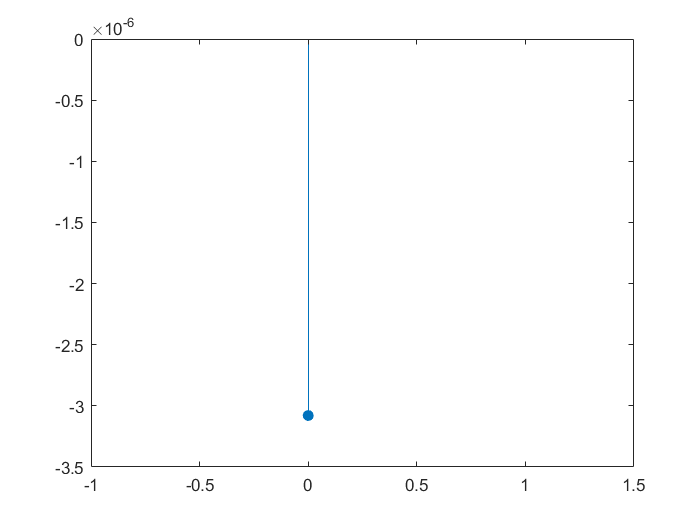

wholeData = 'a = -1.0000000000 && b = 0.0000000000 && x(1) = -0.0395107621'

wholeData = 'a = -1.0000000000 && b = -0.0385131836 && x(2) = -0.0385179873'

Trail_Members = 'x(2): -0.0385179873 we have x(2)-x(1) that is: -0.0000048037 && f(x(2)) is -0.0000030793'

root =     'root finded: -0.0385178684 
     Number of goneStages: 2'


a = -1; %input('enter a: ')
b =  0; %input('enter b: ')
error = 10^(-4); %input('enter error: ')
syms f(x)
figure();
xlabel("x(N)-x(N-1)");
ylabel("f(x(N))");
f(x) = sin(x)*exp(x)+25*x+1;
index_N = 1;
lastOne = 0;
nowOne = 0;
while(true)
    nowOne = (a*f(b)-b*f(a))/(f(b)-f(a));
    wholeData = sprintf('a = %.10f && b = %.10f && x(%d) = %.10f',a,b,index_N,nowOne)
    if(index_N >=2)
    Trail_Members = sprintf('x(%d): %.10f we have x(%d)-x(%d) that is: %.10f && f(x(%d)) is %.10f',index_N,nowOne,index_N,index_N-1,nowOne-lastOne,index_N,f(nowOne))  
    stem(abs(nowOne-lastOne),f(nowOne),'filled')
    hold on
    end
    if((index_N >= 2) && (abs((nowOne - lastOne)<error || f(nowOne) == 0 )))
        root = sprintf('root finded: %.10f \nNumber of goneStages: %d',rootFinder,index_N)
        break;
    end
    if(f(c)*f(a) < 0)
        b = c;
    else
        a = c;  
    end 
    lastOne = c;
index_N = index_N + 1;    
end

# Second Problem

***Solve The equation(finding the roots) via Newton Method***

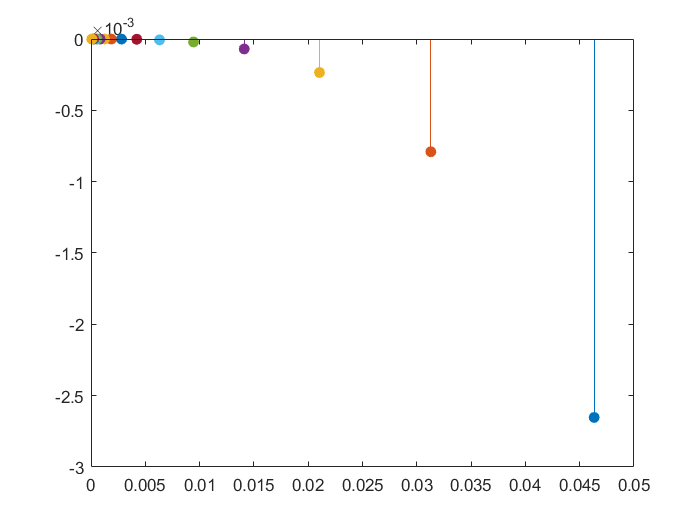

Trail_Members = 'x(1): 0.5463286000 we Have x(1)-x(0) that is:0.0463286000 && f(x(1)) is -0.0026528249: '

Trail_Members = 'x(2): 0.5776202877 we Have x(2)-x(1) that is:0.0312916877 && f(x(2)) is -0.0007901153: '

Trail_Members = 'x(3): 0.5986628819 we Have x(3)-x(2) that is:0.0210425942 && f(x(3)) is -0.0002349174: '

Trail_Members = 'x(4): 0.6127722170 we Have x(4)-x(3) that is:0.0141093351 && f(x(4)) is -0.0000697651: '

Trail_Members = 'x(5): 0.6222144932 we Have x(5)-x(4) that is:0.0094422762 && f(x(5)) is -0.0000207027: '

Trail_Members = 'x(6): 0.6285253901 we Have x(6)-x(5) that is:0.0063108969 && f(x(6)) is -0.0000061404: '

Trail_Members = 'x(7): 0.6327397929 we Have x(7)-x(6) that is:0.0042144028 && f(x(7)) is -0.0000018206: '

Trail_Members = 'x(8): 0.6355525692 we Have x(8)-x(7) that is:0.0028127763 && f(x(8)) is -0.0000005397: '

Trail_Members = 'x(9): 0.6374291647 we Have x(9)-x(8) that is:0.0018765956 && f(x(9)) is -0.0000001600: '

Trail_Members = 'x(10): 0.6386808559 we Have x(10)-x(9) that is:0.0012516912 && f(x(10)) is -0.0000000474: '

Trail_Members = 'x(11): 0.6395155956 we Have x(11)-x(10) that is:0.0008347397 && f(x(11)) is -0.0000000140: '

Trail_Members = 'x(12): 0.6400722127 we Have x(12)-x(11) that is:0.0005566171 && f(x(12)) is -0.0000000042: '

Trail_Members = 'x(13): 0.6404433459 we Have x(13)-x(12) that is:0.0003711332 && f(x(13)) is -0.0000000012: '

Trail_Members = 'x(14): 0.6406907925 we Have x(14)-x(13) that is:0.0002474466 && f(x(14)) is -0.0000000004: '

Trail_Members = 'x(15): 0.6408557678 we Have x(15)-x(14) that is:0.0001649753 && f(x(15)) is -0.0000000001: '

Trail_Members = 'x(16): 0.6409657562 we Have x(16)-x(15) that is:0.0001099884 && f(x(16)) is -0.0000000000: '

Trail_Members = 'x(17): 0.6410390839 we Have x(17)-x(16) that is:0.0000733277 && f(x(17)) is -0.0000000000: '

root =     'root finded:0.6410390839 
     Number of goneStages: 17'


x0 = 0.5; %input('enter the approximate root: '); 0.5 was my quess
syms f(x)
figure();
xlabel("|x(N)-x(N-1)|");
ylabel("f(x(N))");
f(x) = x^3 - (3*x^2)*(2^(-x)) + 3*x*(4^(-x)) - 8^(-x);
df = diff(f,x);
index_N = 1;
while(true)
    x1 = vpa(x0 - (f(x0)/vpa(df(x0))));
    stem(abs(x1-x0),f(x1),'filled')
    hold on
    Trail_Members = sprintf('x(%d): %.10f we Have x(%d)-x(%d) that is:%.10f && f(x(%d)) is %.10f: ',index_N,x1,index_N,index_N-1,x1-x0,index_N,f(x1))
    if(f(x1) == 0 ||  abs(x1-x0)< 10^(-4)) % we use 10^(-4) as the HW says
        root = sprintf('root finded:%.10f \nNumber of goneStages: %d',x1,index_N)
        break;
    end
 index_N = index_N + 1; 
    x0 = x1;
end

# `Second problem(Question)`

## `The answer of the asked Question:`

`why convergence is not quadratic `

`lests take a look at the differential of the f(x) which is at the below :`

$\mathrm{diff}\left(x\right)=\;\frac{\log \left(8\right)}{8^x }-\frac{6 x}{2^x }+\frac{3}{4^x }+3 x^2 -\frac{3 x \log \left(4\right)}{4^x }+\frac{3 x^2  \log \left(2\right)}{2^x }$ ( it is also a matlab output!)

`as we know the newton Method converges to the root quadratically but as we read in `

`the proof we thought that the differential of the main mathod(f(x)) is not zero but`

`in this example i will show you that by converging to the main root we will find out that `

`the differential of the f(x) at x = root converges to zero`

`thus the newton method is not quadratically converged anymore (because we had thought that`

`diff(x) at x = root is not zero ( the root should be a simple root (not more!))`

`now i wanna show You that the x(n) seauences converges to the root that satisfies the equation `

`diff(root (= lim x(n) when n --> infinity)  = 0`

`lets see ( i decreased the error from 10^-4 to 10^-8 in order to show that diff(x) converges to the zero when the `

`x(n) sequences converges to the root (it is also an obvious fact in the graph)`

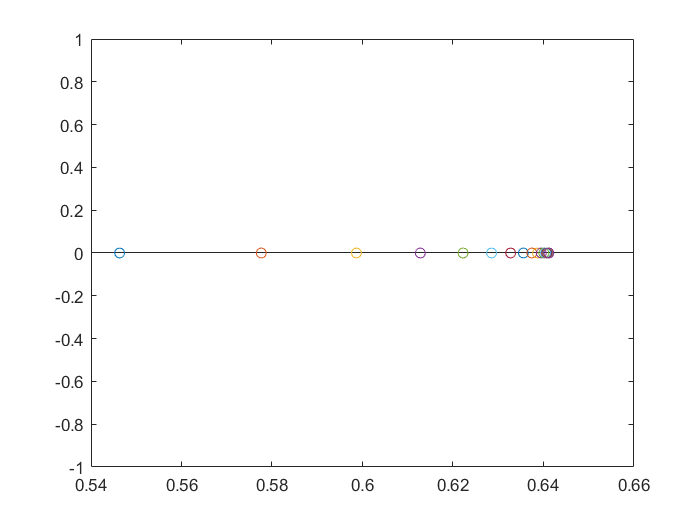

Trail_Members = 'x(1): 0.546329 we Have diff(x) that is:0.0847773045425018190179855537280673161149 : '

Trail_Members = 'x(2): 0.577620 we Have diff(x) that is:0.0375483765996570753586958346659230301157 : '

Trail_Members = 'x(3): 0.598663 we Have diff(x) that is:0.0166497876610865735980127055881894193590 : '

Trail_Members = 'x(4): 0.612772 we Have diff(x) that is:0.0073885869874719773894855556761740444927 : '

Trail_Members = 'x(5): 0.622214 we Have diff(x) that is:0.0032804733688065529015331911466546443990 : '

Trail_Members = 'x(6): 0.628525 we Have diff(x) that is:0.0014569997326312842528261981556170212571 : '

Trail_Members = 'x(7): 0.632740 we Have diff(x) that is:0.0006472629864289406028884932275957453385 : '

Trail_Members = 'x(8): 0.635553 we Have diff(x) that is:0.0002875858693286857843685044855419619125 : '

Trail_Members = 'x(9): 0.637429 we Have diff(x) that is:0.0001277903082231338592871655590599289098 : '

Trail_Members = 'x(10): 0.638681 we Have diff(x) that is:0.0000567881006163810909633839207888428291 : '

Trail_Members = 'x(11): 0.639516 we Have diff(x) that is:0.0000252369070107942538563807616247558485 : '

Trail_Members = 'x(12): 0.640072 we Have diff(x) that is:0.0000112157369259859946770312502661859355 : '

Trail_Members = 'x(13): 0.640443 we Have diff(x) that is:0.0000049845746025411876440193263693156922 : '

Trail_Members = 'x(14): 0.640691 we Have diff(x) that is:0.0000022153080165770806405874712025072526 : '

Trail_Members = 'x(15): 0.640856 we Have diff(x) that is:0.0000009845640162144100648649799878420197 : '

Trail_Members = 'x(16): 0.640966 we Have diff(x) that is:0.0000004375788742183334060055575204239986 : '

Trail_Members = 'x(17): 0.641039 we Have diff(x) that is:0.0000001944779788053879659826499301175651 : '

Trail_Members = 'x(18): 0.641088 we Have diff(x) that is:0.0000000864342066329812473885030430116594 : '

Trail_Members = 'x(19): 0.641121 we Have diff(x) that is:0.0000000384150694342631998807019954016856 : '

Trail_Members = 'x(20): 0.641142 we Have diff(x) that is:0.0000000170733246336766777010266491008267 : '

Trail_Members = 'x(21): 0.641157 we Have diff(x) that is:0.0000000075881325604094442347537298227018 : '

Trail_Members = 'x(22): 0.641166 we Have diff(x) that is:0.0000000033724998872380027956125856552268 : '

Trail_Members = 'x(23): 0.641173 we Have diff(x) that is:0.0000000014988878097542756033350809302326 : '

Trail_Members = 'x(24): 0.641177 we Have diff(x) that is:0.0000000006661720549969642881991409846191 : '

Trail_Members = 'x(25): 0.641180 we Have diff(x) that is:0.0000000002960763785487170737666317253938 : '

Trail_Members = 'x(26): 0.641182 we Have diff(x) that is:0.0000000001315894748101664910321583874212 : '

Trail_Members = 'x(27): 0.641183 we Have diff(x) that is:0.0000000000584842030957689850140417302483 : '

Trail_Members = 'x(28): 0.641184 we Have diff(x) that is:0.0000000000259929768037582482088996491358 : '

Trail_Members = 'x(29): 0.641185 we Have diff(x) that is:0.0000000000115524334387321398928440240504 : '

Trail_Members = 'x(30): 0.641185 we Have diff(x) that is:0.0000000000051344146553560808886708845482 : '

Trail_Members = 'x(31): 0.641185 we Have diff(x) that is:0.0000000000022819620079204418194525387863 : '

Trail_Members = 'x(32): 0.641185 we Have diff(x) that is:0.0000000000010142053187419142901906564752 : '

Trail_Members = 'x(33): 0.641186 we Have diff(x) that is:0.0000000000004507579140744465068299472296 : '

Trail_Members = 'x(34): 0.641186 we Have diff(x) that is:0.0000000000002003368491097083004023000787 : '

Trail_Members = 'x(35): 0.641186 we Have diff(x) that is:0.0000000000000890385991331901628175201687 : '

Trail_Members = 'x(36): 0.641186 we Have diff(x) that is:0.0000000000000395727105862698127917056874 : '

Trail_Members = 'x(37): 0.641186 we Have diff(x) that is:0.0000000000000175878713303147339280092188 : '

Trail_Members = 'x(38): 0.641186 we Have diff(x) that is:0.0000000000000078168316901070714452124269 : '

Trail_Members = 'x(39): 0.641186 we Have diff(x) that is:0.0000000000000034741474141942443879623680 : '

root =     'root finded:0.641186 
     Number of goneStages: 39'


x0 = 0.5; %input('enter the approximate root: '); 0.5 was my quess
syms f(x)
figure();
xlabel("|x(N)-x(N-1)|");
ylabel("f(x(N))");
f(x) = x^3 - (3*x^2)*(2^(-x)) + 3*x*(4^(-x)) - 8^(-x);
df = diff(f,x);
index_N = 1;
while(true)
    x1 = vpa(x0 - (f(x0)/vpa(df(x0))));
    stem(x1, diff(x1))
    hold on
    Trail_Members = sprintf('x(%d): %.6f we Have diff(x) that is:%.40f : ',index_N,x1,vpa(df(x1)))
    if(f(x1) == 0 ||  abs(x1-x0)< 10^(-8)) % we use 10^(-4) as the HW says
        root = sprintf('root finded:%.6f \nNumber of goneStages: %d',x1,index_N)
        break;
    end
 index_N = index_N + 1; 
    x0 = x1;
end